debug_mode = logical
   0


imgs_proc = 0

For Hokkaido Iburi-Tobu ||| Took 133.4s
For Jiuzhai valley (UAV-0.2m) ||| Took 574.9s
For Jiuzhai valley (UAV-0.5m) ||| Took 174.8s
For Lombok ||| Took 42.0s
For Longxi River(SAT) ||| Took 172.5s
For Mengdong Township ||| Took 111.2s
For Moxi town(UAV-0.2m) ||| Took 751.7s
For Moxi town(UAV-1m) ||| Took 15.3s
For Moxitaidi (SAT) ||| Took 62.1s
For Moxitaidi (UAV-0.6m) ||| Took 92.8s
For Moxitaidi (UAV-1m) ||| Took 45.3s
For Tiburon Peninsula(planet) ||| Took 30.2s
For Wenchuan ||| Took 16.6s
For palu ||| Took 78.9s


Total processing time: 2302.8s

For Hokkaido Iburi-Tobu ||| Stats:


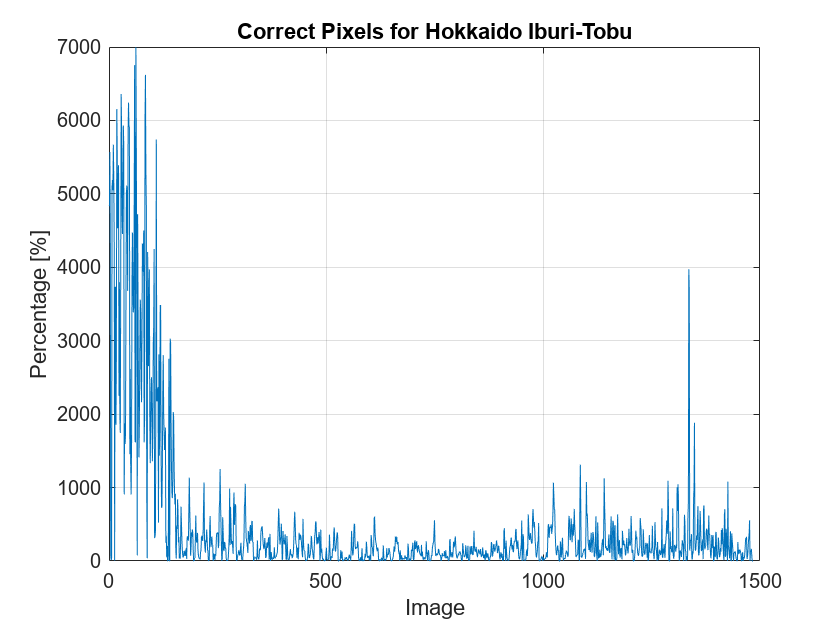

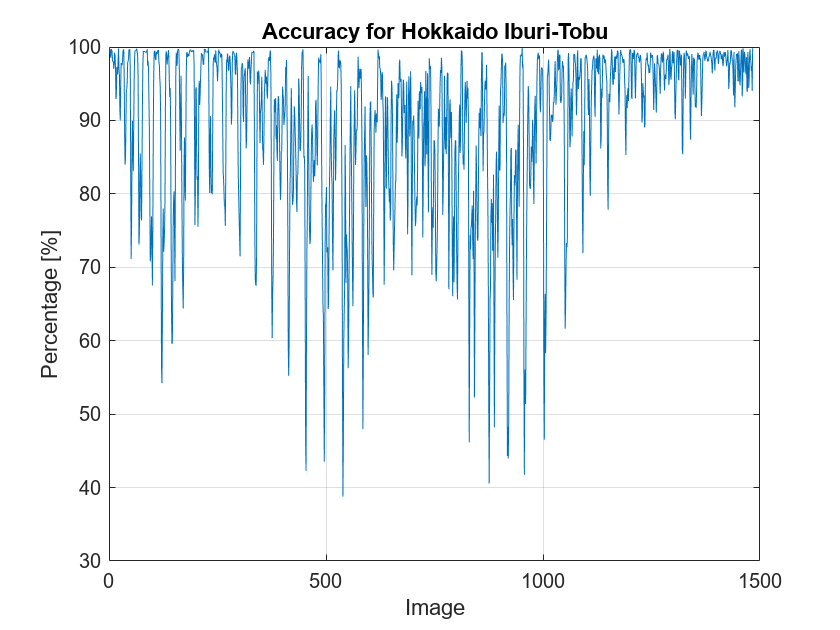

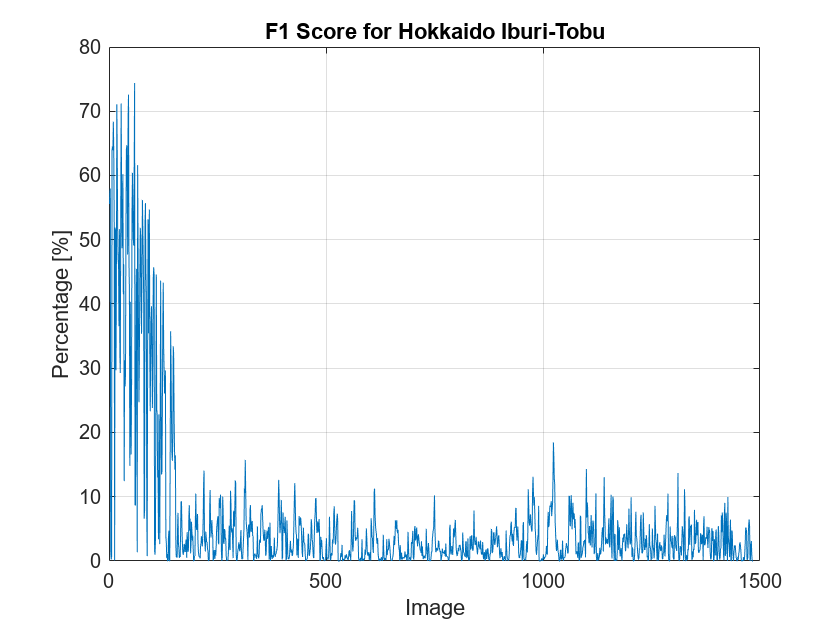

For Jiuzhai valley (UAV-0.2m) ||| Stats:


For Jiuzhai valley (UAV-0.5m) ||| Stats:


For Lombok ||| Stats:


For Longxi River(SAT) ||| Stats:


For Mengdong Township ||| Stats:


For Moxi town(UAV-0.2m) ||| Stats:


For Moxi town(UAV-1m) ||| Stats:


For Moxitaidi (SAT) ||| Stats:


For Moxitaidi (UAV-0.6m) ||| Stats:


For Moxitaidi (UAV-1m) ||| Stats:


For Tiburon Peninsula(planet) ||| Stats:


For Wenchuan ||| Stats:


For palu ||| Stats:


overall_correct_landslide = 5.1918

overall_pix_correct_landslide = 0

overall_precision = 0.0519

overall_pix_precision = 0.0519

overall_recall = 0.2316

overall_pix_recall = 0.2316

overall_f1_score = 0.0633

overall_pix_f1_score = 0.0633

overall_accuracy = 0.8933

overall_pix_accuracy = 0.8933

clc; clear; close all;

debug_mode = false
imgs_proc = 0
% Directories
orig_dir = 'C:\Users\andre\EE581-LandlideProj\data\original_dataset\';
output_dir = 'C:\Users\andre\Year5\EE581\Project\Datasets\Masks\Masks_CAS\';

% Get list of folders inside directory
folders = dir(orig_dir);
folders = {folders([folders.isdir]).name}; % Get only folder names
folders = folders(~ismember(folders, {'.', '..', ...
    'Longxi River(UAV)','Tiburon Peninsula(Sentinel)'})); % Remove

% Set up stats storage
true_pos = cell(numel(folders),1); % Cell array - folder per row
false_pos = cell(numel(folders),1);
true_neg = cell(numel(folders),1);
false_neg = cell(numel(folders),1);
precision = cell(numel(folders),1);
recall = cell(numel(folders),1);
f1_score = cell(numel(folders),1);
accuracy = cell(numel(folders),1);
precision_per_set = cell(1,numel(folders));
recall_per_set = cell(1,numel(folders));
f1_score_per_set = cell(1,numel(folders));
accuracy_per_set = cell(1,numel(folders));
correct_landslide = cell(numel(folders),1);
correct_landslide_per_set = cell(numel(folders),1);

local_true_pos = cell(numel(folders),1);
local_false_pos = cell(numel(folders),1);
local_true_neg = cell(numel(folders),1);
local_false_neg = cell(numel(folders),1);
local_precision = cell(numel(folders),1);
local_recall = cell(numel(folders),1);
local_f1_score = cell(numel(folders),1);
local_accuracy = cell(numel(folders),1);
local_precision_per_set = cell(1,numel(folders));
local_recall_per_set = cell(1,numel(folders));
local_f1_score_per_set = cell(1,numel(folders));
local_accuracy_per_set = cell(1,numel(folders));

% Loop through each folder & assign zero array of its image count
for i=1:numel(folders)
    list_imgs = dir(fullfile(orig_dir, folders{i}, 'img', '*.tif')); % Get images
    list_lbls = dir(fullfile(orig_dir, folders{i}, 'label', '*.tif')); % Get images
    % Ensure corresponding images and labels exist
    if numel(list_imgs) ~= numel(list_lbls)
        warning('Mismatch in image-label count for folder: %s', folders{i});
    else
        true_pos{i} = zeros(1,numel(list_imgs)); % Each cell contains image count
        false_pos{i} = zeros(1,numel(list_imgs));
        true_neg{i} = zeros(1,numel(list_imgs));
        false_neg{i} = zeros(1,numel(list_imgs));
        precision{i} = zeros(1,numel(list_imgs));
        recall{i} = zeros(1,numel(list_imgs));
        f1_score{i} = zeros(1,numel(list_imgs));
        accuracy{i} = zeros(1,numel(list_imgs));
        correct_landslide{i} = zeros(1,numel(list_imgs));
        
        local_true_pos{i} = zeros(1,numel(list_imgs));
        local_false_pos{i} = zeros(1,numel(list_imgs));
        local_true_neg{i} = zeros(1,numel(list_imgs));
        local_false_neg{i} = zeros(1,numel(list_imgs));
        local_precision{i} = zeros(1,numel(list_imgs));
        local_recall{i} = zeros(1,numel(list_imgs));
        local_f1_score{i} = zeros(1,numel(list_imgs));
        local_accuracy{i} = zeros(1,numel(list_imgs));
    end
end

% Iterate through each folder
t1 = datetime('now');
for i=1:numel(folders)
    % Directory
    img_dir = fullfile(orig_dir, folders{i}, 'img');
    lbl_dir = fullfile(orig_dir, folders{i}, 'label');

    % Get list of image and label files
    list_imgs = dir(fullfile(img_dir, '*.tif'));
    list_lbls = dir(fullfile(lbl_dir, '*.tif'));
    
    % Create folder to output masks
    if ~exist(fullfile(output_dir,folders{i}), 'dir')
        mkdir(output_dir,folders{i}); % Create folder if doesn't exist
    end

    % Ensure corresponding images and labels exist
    if numel(list_imgs) ~= numel(list_lbls)
        warning('Mismatch in image-label count for folder: %s', folders{i});
    else

        % Iterate through each image (and label) of each folder
        t2 = datetime('now');
        for k = 1:numel(list_imgs)
            imgs_proc = imgs_proc + 1;
            % Directory
            img_path = fullfile(img_dir, list_imgs(k).name);
            lbl_path = fullfile(lbl_dir, list_lbls(k).name);
    
            % Load data and label
            img = double(imread(img_path));
            label = double(imread(lbl_path));
    
            % Normalize images
            if max(img(:)) > 1
                img = img / max(img(:)); % Scale to [0, 1]
            end
            if max(label(:)) > 1
                label = label / max(label(:)); % Scale to [0, 1]
            end

            % Binarise the label and invert it so landslied is 1
            
            label_temp = label;
            label_temp(label_temp == 255) = 1;
            label_bin = (label_temp(:,:,1) + label_temp(:,:,2) + label_temp(:,:,3)) > 0;
            label = 1 - label_bin;    
            img_hsv = rgb2hsv(img);
    
            % Super sample - use interpolation to increase resolution
            scale_factor = 2;
            img_hsv = imresize(img_hsv, scale_factor, 'bicubic'); % Think bicubic is the best
        
            % Convert into HSV format and exctract CHs
            R_CH = img(:,:,1); % Red CH
            G_CH = img(:,:,2); % Green CH
            B_CH = img(:,:,3); % Blue CH
            H_CH = img_hsv(:,:,1); % Hue CH
            S_CH = img_hsv(:,:,2); % Saturation CH
            V_CH = img_hsv(:,:,3); % Value CH
        
            % Reduce contrast
            H_mask = H_CH;
            H_mask = histeq(H_mask);
            H_thresh = 0.85;
            H_mask_bin = H_mask >= H_thresh;
            V_mask = V_CH;
            V_mask = histeq(V_mask);
            V_thresh = 0.85;
            V_mask_bin = V_mask >= V_thresh;
        
            % Match areas where landslides could be
            Mask_HV = H_mask_bin & V_mask_bin;
        
            % Remove very small patches by assuming they are like 'salt and pepper' noise
            Mask_HV_denoised = medfilt2(Mask_HV, [3 3]);
            
            % Fill gaps where landslides could be and return image to normal size
            Mask_HV_denoised_closed = imclose(Mask_HV_denoised, strel('disk', 5)); % Fill gaps
            mask = imresize(Mask_HV_denoised_closed, [size(img,1), size(img,2)], 'nearest');
    
            Mask_HV_denoised_closed1 = imclose(Mask_HV_denoised, strel('disk', 7)); % Fill gaps
            mask1 = imresize(Mask_HV_denoised_closed1, [size(img,1), size(img,2)], 'nearest');
            
            % Statistcally analyse results
            true_pos{i}(k) = sum(label & mask, 'all');
            false_pos{i}(k) = sum(label & ~mask, 'all');
            true_neg{i}(k) = sum(~label & ~mask, 'all');
            false_neg{i}(k) = sum(~label & mask, 'all');
            accuracy{i}(k) = (true_pos{i}(k) + true_neg{i}(k)) / (true_pos{i}(k) + true_neg{i}(k) + false_pos{i}(k) + false_neg{i}(k));
            if (true_pos{i}(k) + false_pos{i}(k)) == 0
                precision{i}(k) = 0;
            else
                precision{i}(k) = true_pos{i}(k) / (true_pos{i}(k) + false_pos{i}(k));
            end
            if (true_pos{i}(k) + false_neg{i}(k)) == 0
                recall{i}(k) = 0;
            else
                recall{i}(k) = true_pos{i}(k) / (true_pos{i}(k) + false_neg{i}(k));
            end
            if (precision{i}(k) + recall{i}(k)) == 0
                f1_score{i}(k) = 0;
            else
                f1_score{i}(k) = (2 * precision{i}(k) * recall{i}(k)) / (precision{i}(k) + recall{i}(k));
            end

            % Statistcally analyse results
            labelled_pixs = (label == 1); % Logical mask of landslide locations
            % Compare mask w/ label directly
            local_true_pos{i}(k) = sum(labelled_pixs & (mask == 1), 'all'); % Landlside in label & mask
            local_false_pos{i}(k) = sum(labelled_pixs & (mask == 0), 'all'); % Landlside in label & mask
            local_true_neg{i}(k) = sum(~labelled_pixs & (mask == 0), 'all'); % Landlside in label & mask
            local_false_neg{i}(k) = sum(~labelled_pixs & (mask == 1), 'all'); % Landlside in label & mask
            
            local_accuracy{i}(k) = (local_true_pos{i}(k) + local_true_neg{i}(k)) / (local_true_pos{i}(k) + local_true_neg{i}(k) + local_false_pos{i}(k) + local_false_neg{i}(k));
            if (local_true_pos{i}(k) + local_false_pos{i}(k)) == 0
                local_precision{i}(k) = 0;
            else
                local_precision{i}(k) = local_true_pos{i}(k) / (local_true_pos{i}(k) + local_false_pos{i}(k));
            end
            if (local_true_pos{i}(k) + local_false_neg{i}(k)) == 0
                local_recall{i}(k) = 0;
            else
                local_recall{i}(k) = local_true_pos{i}(k) / (local_true_pos{i}(k) + local_false_neg{i}(k));
            end
            if (local_precision{i}(k) + local_recall{i}(k)) == 0
                local_f1_score{i}(k) = 0;
            else
                local_f1_score{i}(k) = (2 * local_precision{i}(k) * local_recall{i}(k)) / (local_precision{i}(k) + local_recall{i}(k));
            end
            
            % Locally
            %[x_lbl, y_lbl] = find(label); % Locations within labelled
            %correct_pix = mask(sub2ind(size(mask), x_lbl, y_lbl)) == 1; % Logical array to compare - correctly identified 
            %fprintf("For %s Result=%.1f\n", folders{i}, local_true_pos{i}(k)/sum(label(:))*100);    
            correct_landslide{i}(k) = local_true_pos{i}(k)/sum(label(:))*100;
            output_file = fullfile(output_dir,folders{i},list_imgs(k).name);
            imwrite(mask,output_file);
        end
    end
    t3 = datetime('now');
    elapsedTime = seconds(t3-t2); % Cacluate elapsed times
    fprintf("For %s ||| Took %.1fs\n", folders{i} , elapsedTime);    
end
t3 = datetime('now');
elapsedTime = seconds(t3-t1); % Cacluate elapsed times
fprintf("Total processing time: %.1fs", elapsedTime);    

% Loop through each folder to compute stats
for i=1:numel(folders)
    list_imgs = dir(fullfile(orig_dir, folders{i}, 'img', '*.tif')); % Get images
    list_lbls = dir(fullfile(orig_dir, folders{i}, 'label', '*.tif')); % Get images
    % Ensure corresponding images and labels exist
    if numel(list_imgs) ~= numel(list_lbls)
        warning('Mismatch in image-label count for folder: %s', folders{i});
    else
        % Create folder to output masks
        if ~exist(fullfile(output_dir,'Plots'), 'dir')
            mkdir(output_dir,'Plots');
        end
        %fprintf("For %s ||| Stats:\n", folders{i});

        % Calc stats per set
        correct_landslide_per_set{i} = mean((correct_landslide{i}));
        precision_per_set{i} = mean((precision{i}));
        recall_per_set{i} = mean((recall{i}));
        f1_score_per_set{i} = mean((f1_score{i}));
        accuracy_per_set{i} = mean((accuracy{i}));
        
        % Plot statistics
        figure;
        plot(1:numel(list_imgs),correct_landslide{i}(:));
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Correct Pixels for %s", folders{i}));
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Correct_Landslide_%s.png',folders{i}));
        saveas(gcf, output_file); % Save current figure
        close(gcf); % Close figure to avoid memory usage
        figure;
        plot(1:numel(list_imgs),accuracy{i}(:)*100);
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Accuracy for %s", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Accuracy_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        plot(1:numel(list_imgs),precision{i}(:)*100);
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Precision for %s", folders{i}))
        grid on;
        ylim([0 100]);
        output_file = fullfile(output_dir,'Plots',sprintf('Precision_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        plot(1:numel(list_imgs),recall{i}(:)*100);
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Recall for %s", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Recall_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        plot(1:numel(list_imgs),f1_score{i}(:)*100);
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("F1 Score for %s", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('F1_Score_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        plot(1:numel(folders),correct_landslide_per_set{i}(:)*100);
        xlabel('Image');
        ylabel('Percentage [%]');
        title("Correct Pixels per set");
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots','Correct_Landslide.png');
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        plot(1:numel(folders),accuracy_per_set{i}(:)*100);
        xlabel('Set');
        ylabel('Percentage [%]');
        title("Accuracy per Set")
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots','Accuracy.png');
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        plot(1:numel(folders),precision_per_set{i}(:)*100);
        xlabel('Set');
        ylabel('Percentage [%]');
        title("Precision per Set")
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots','Precision.png');
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        plot(1:numel(folders),recall_per_set{i}(:)*100);
        xlabel('Set');
        ylabel('Percentage [%]');
        title("Recall per Set")
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots','Recall.png');
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        plot(1:numel(folders),f1_score_per_set{i}(:)*100);
        xlabel('Set');
        ylabel('Percentage [%]');
        title("F1 Score per Set")
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots','F1_Score.png');
        saveas(gcf, output_file);
        close(gcf); 

        % Calc stats per set
        local_precision_per_set{i} = mean((local_precision{i}));
        local_recall_per_set{i} = mean((local_recall{i}));
        local_f1_score_per_set{i} = mean((local_f1_score{i}));
        local_accuracy_per_set{i} = mean((local_accuracy{i}));
        
        % Plot statistics
        figure;
        plot(1:numel(list_imgs),local_accuracy{i}(:)*100);
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Accuracy for %s (Landslide Pixels)", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Accuracy_Pix_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        plot(1:numel(list_imgs),local_precision{i}(:)*100);
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Precision for %s (Landslide Pixels)", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Precision_Pix_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        plot(1:numel(list_imgs),local_recall{i}(:)*100);
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Recall for %s (Landslide Pixels)", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Recall_Pix_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        plot(1:numel(list_imgs),local_f1_score{i}(:)*100);
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("F1 Score for %s (Landslide Pixels)", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('F1_Score_Pix_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        plot(1:numel(folders),local_accuracy_per_set{i}(:)*100);
        xlabel('Set');
        ylabel('Percentage [%]');
        title("Accuracy per Set (Landslide Pixels)")
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots','Accuracy_Pix.png');
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        plot(1:numel(folders),local_precision_per_set{i}(:)*100);
        xlabel('Set');
        ylabel('Percentage [%]');
        title("Precision per Set (Landslide Pixels)")
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots','Precision_Pix.png');
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        plot(1:numel(folders),local_recall_per_set{i}(:)*100);
        xlabel('Set');
        ylabel('Percentage [%]');
        title("Recall per Set (Landslide Pixels)")
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots','Recall_Pix.png');
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        plot(1:numel(folders),local_f1_score_per_set{i}(:)*100);
        xlabel('Set');
        ylabel('Percentage [%]');
        title("F1 Score per Set (Landslide Pixels)")
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots','F1_Score_Pix.png');
        saveas(gcf, output_file);
        close(gcf); 
    end
end

overall_correct_landslide = mean(cell2mat(correct_landslide_per_set))
overall_precision = mean(cell2mat(precision_per_set))
overall_pix_precision = mean(cell2mat(local_precision_per_set))
overall_recall = mean(cell2mat(recall_per_set))
overall_pix_recall = mean(cell2mat(local_recall_per_set))
overall_f1_score = mean(cell2mat(f1_score_per_set))
overall_pix_f1_score = mean(cell2mat(local_f1_score_per_set))
overall_accuracy= mean(cell2mat(accuracy_per_set))
overall_pix_accuracy= mean(cell2mat(local_accuracy_per_set))

clear all

clc; clear; close all;

imgs_proc = 0;

% Directories
orig_dir = 'C:\Users\andre\Year5\EE581\Project\Datasets\archive\TrainData\';
output_dir = 'C:\Users\andre\Year5\EE581\Project\Datasets\Masks_Sense\Masks_CAS\';

% Get list of folders inside directory
folders = dir(orig_dir);
folders = {folders([folders.isdir]).name}; % Get only folder names
folders = folders(~ismember(folders, {'.', '..'})); % Remove

% Set up stats storage
% Assign zero array of its image count
list_imgs = dir(fullfile(orig_dir, folders{1}, '*.h5')); % Get images
list_lbls = dir(fullfile(orig_dir, folders{2}, '*.h5')); % Get labels
% Ensure corresponding images and labels exist
if numel(list_imgs) ~= numel(list_lbls)
    warning('Mismatch in image-label count');
else
    true_pos = zeros(1,numel(list_imgs));
    false_pos = zeros(1,numel(list_imgs));
    true_neg = zeros(1,numel(list_imgs));
    false_neg = zeros(1,numel(list_imgs));
    precision = zeros(1,numel(list_imgs));
    recall = zeros(1,numel(list_imgs));
    f1_score = zeros(1,numel(list_imgs));
    accuracy = zeros(1,numel(list_imgs));
    correct_landslide = zeros(1,numel(list_imgs));
        
    local_true_pos = zeros(1,numel(list_imgs));
    local_false_pos = zeros(1,numel(list_imgs));
    local_true_neg = zeros(1,numel(list_imgs));
    local_false_neg = zeros(1,numel(list_imgs));
    local_precision = zeros(1,numel(list_imgs));
    local_recall = zeros(1,numel(list_imgs));
    local_f1_score = zeros(1,numel(list_imgs));
    local_accuracy = zeros(1,numel(list_imgs));
end

% Go through through folder
t1 = datetime('now');
% Get list of image and label files
list_imgs = dir(fullfile(orig_dir, folders{1}, '*.h5')); % Get images
list_lbls = dir(fullfile(orig_dir, folders{2}, '*.h5')); % Get labels

% Create folder for all outputs
if ~exist(output_dir,'dir')
    mkdir(output_dir); % Create folder if doesn't exist
end

% Ensure corresponding images and labels exist
if numel(list_imgs) ~= numel(list_lbls)
    warning('Mismatch in image-label count for folder: %s', folders{i});
else
    % Iterate through each image (and label) of each folder
    t2 = datetime('now');

    % Create folder to output masks
    if ~exist(fullfile(output_dir,'Mask'),'dir')
        mkdir(output_dir,'Mask'); % Create folder if doesn't exist
    end

    for k = 1:numel(list_imgs)
        imgs_proc = imgs_proc + 1;
        % Full path
        img_path = fullfile(orig_dir, folders{1}, list_imgs(k).name);
        lbl_path = fullfile(orig_dir, folders{2}, list_lbls(k).name);

        % Read HDF5 data
        img_info = h5info(img_path);
        img_name = img_info.Datasets(1).Name;
        img_chs = h5read(img_path, ['/' img_name]);
            
        label_info = h5info(lbl_path);
        label_name = label_info.Datasets(1).Name;
        label = h5read(lbl_path, ['/' label_name]);

        % Binarise image
        label = label > 0;

        % Extract channels
        R_CH = squeeze(img_chs(4,:,:));
        G_CH = squeeze(img_chs(3,:,:));
        B_CH = squeeze(img_chs(2,:,:));

        % Combine into an RGB image & label
        img = double(cat(3, R_CH, G_CH, B_CH));
        
        % Normalize images
        if max(img(:)) > 1
            img = img / max(img(:)); % Scale to [0, 1]
        end
        
        img_hsv = rgb2hsv(img);
            
        % Super sample - use interpolation to increase resolution
        scale_factor = 2;
        img_hsv = imresize(img_hsv, scale_factor, 'bicubic'); % Think bicubic is the best
        
        % Convert into HSV format and exctract CHs
        H_CH = img_hsv(:,:,1); % Hue CH
        S_CH = img_hsv(:,:,2); % Saturation CH
        V_CH = img_hsv(:,:,3); % Value CH
        
        % Reduce contrast
        H_mask = H_CH;
        H_mask = histeq(H_mask);
        H_thresh = 0.85;
        H_mask_bin = H_mask >= H_thresh;
        V_mask = V_CH;
        V_mask = histeq(V_mask);
        V_thresh = 0.85;
        V_mask_bin = V_mask >= V_thresh;
        
        % Match areas where landslides could be
        Mask_HV = H_mask_bin & V_mask_bin;
        
        % Remove very small patches by assuming they are like 'salt and pepper' noise
        Mask_HV_denoised = medfilt2(Mask_HV, [3 3]);
            
        % Fill gaps where landslides could be and return image to normal size
        Mask_HV_denoised_closed = imclose(Mask_HV_denoised, strel('disk', 5)); % Fill gaps
        mask = imresize(Mask_HV_denoised_closed, [size(img,1), size(img,2)], 'nearest');
    
        Mask_HV_denoised_closed1 = imclose(Mask_HV_denoised, strel('disk', 7)); % Fill gaps
        mask1 = imresize(Mask_HV_denoised_closed1, [size(img,1), size(img,2)], 'nearest');
            
        % Statistcally analyse results
        true_pos(k) = sum(label & mask, 'all');
        false_pos(k) = sum(label & ~mask, 'all');
        true_neg(k) = sum(~label & ~mask, 'all');
        false_neg(k) = sum(~label & mask, 'all');
        accuracy(k) = (true_pos(k) + true_neg(k)) / (true_pos(k) + true_neg(k) + false_pos(k) + false_neg(k));
        if (true_pos(k) + false_pos(k)) == 0
            precision(k) = 0;
        else
            precision(k) = true_pos(k) / (true_pos(k) + false_pos(k));
        end
        if (true_pos(k) + false_neg(k)) == 0
            recall(k) = 0;
        else
            recall(k) = true_pos(k) / (true_pos(k) + false_neg(k));
        end
        if (precision(k) + recall(k)) == 0
            f1_score(k) = 0;
        else
            f1_score(k) = (2 * precision(k) * recall(k)) / (precision(k) + recall(k));
        end

        % Statistcally analyse results
        labelled_pixs = (label == 1); % Logical mask of landslide locations
        % Compare mask w/ label directly
        local_true_pos(k) = sum(labelled_pixs & (mask == 1), 'all'); % Landlside in label & mask
        local_false_pos(k) = sum(labelled_pixs & (mask == 0), 'all'); % Landlside in label & mask
        local_true_neg(k) = sum(~labelled_pixs & (mask == 0), 'all'); % Landlside in label & mask
        local_false_neg(k) = sum(~labelled_pixs & (mask == 1), 'all'); % Landlside in label & mask
        
        local_accuracy(k) = (local_true_pos(k) + local_true_neg(k)) / (local_true_pos(k) + local_true_neg(k) + local_false_pos(k) + local_false_neg(k));
        if (local_true_pos(k) + local_false_pos(k)) == 0
            local_precision(k) = 0;
        else
            local_precision(k) = local_true_pos(k) / (local_true_pos(k) + local_false_pos(k));
        end

        if (local_true_pos(k) + local_false_neg(k)) == 0
            local_recall(k) = 0;
        else
            local_recall(k) = local_true_pos(k) / (local_true_pos(k) + local_false_neg(k));
        end
        if (local_precision(k) + local_recall(k)) == 0
            local_f1_score(k) = 0;
        else
            local_f1_score(k) = (2 * local_precision(k) * local_recall(k)) / (local_precision(k) + local_recall(k));
        end

        % Locally
        %[x_lbl, y_lbl] = find(label); % Locations within labelled
        %correct_pix = mask(sub2ind(size(mask), x_lbl, y_lbl)) == 1; % Logical array to compare - correctly identified 
        %fprintf("For %s Result=%.1f\n", folders, local_true_pos(k)/sum(label(:))*100);    
        if sum(label(:)) == 0
            if local_true_pos(k) == 0
                correct_landslide(k) = 100; % ---
            else
                correct_landslide(k) = 0;
            end
        else
            correct_landslide(k) = local_true_pos(k)/sum(label(:))*100;
        end
        mask_name = split(list_imgs(k).name, '.');
        mask_name = [mask_name{1}, '.jpg'];
        output_file = fullfile(output_dir,'Mask',mask_name);
        imwrite(mask,output_file);
    end
end

correct_landslide =      0   100     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



t3 = datetime('now');
elapsedTime = seconds(t3-t1); % Cacluate elapsed times
fprintf("Total processing time: %.1fs", elapsedTime);    

Total processing time: 1.0s

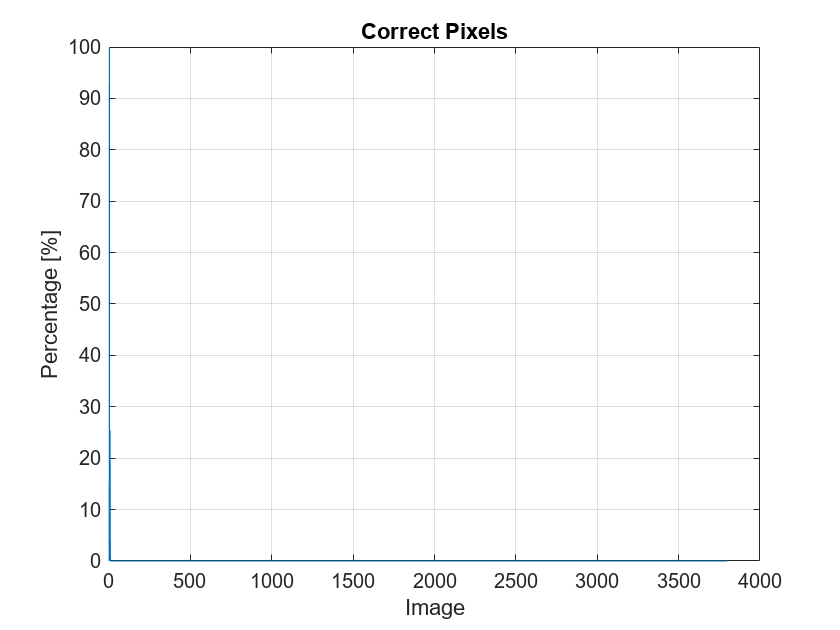

correct_landslide =          0  100.0000         0         0         0    2.2222   25.4190    4.6851    0.1650         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0



% Go through folder to compute stats
list_imgs = dir(fullfile(orig_dir, folders{1}, '*.h5')); % Get images
list_lbls = dir(fullfile(orig_dir, folders{2}, '*.h5')); % Get labels
% Ensure corresponding images and labels exist
if numel(list_imgs) ~= numel(list_lbls)
    warning('Mismatch in image-label count');
else

    % Create folder to output masks
    if ~exist(fullfile(output_dir,'Plots'), 'dir')
        mkdir(output_dir,'Plots');
    end

    % Plot statistics
    figure;
    plot(1:numel(list_imgs),correct_landslide);
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Correct Pixels");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Correct_Landslide.png');
    saveas(gcf, output_file); % Save current figure
    close(gcf); % Close figure to avoid memory usage
    figure;
    plot(1:numel(list_imgs),accuracy*100);
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Accuracy");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Accuracy.png');
    saveas(gcf, output_file);
    close(gcf); 
    figure;
    plot(1:numel(list_imgs),precision*100);
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Precision");
    grid on;
    ylim([0 100]);
    output_file = fullfile(output_dir,'Plots','Precision.png');
    saveas(gcf, output_file);
    close(gcf); 
    figure;
    plot(1:numel(list_imgs),recall*100);
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Recall");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Recall.png');
    saveas(gcf, output_file);
    close(gcf); 
    figure;
    plot(1:numel(list_imgs),f1_score*100);
    xlabel('Image');
    ylabel('Percentage [%]');
    title("F1 Score");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','F1_Score.png');
    saveas(gcf, output_file);
    close(gcf); 
    
    % Plot statistics
    figure;
    plot(1:numel(list_imgs),local_accuracy*100);
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Accuracy (Landslide Pixels)");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Accuracy_Pix.png');
    saveas(gcf, output_file);
    close(gcf);
    figure;
    plot(1:numel(list_imgs),local_precision*100);
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Precision (Landslide Pixels)");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Precision_Pix.png');
    saveas(gcf, output_file);
    close(gcf);
    figure;
    plot(1:numel(list_imgs),local_recall*100);
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Recall (Landslide Pixels)");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Recall_Pix.png');
    saveas(gcf, output_file);
    close(gcf);
    figure;
    plot(1:numel(list_imgs),local_f1_score*100);
    xlabel('Image');
    ylabel('Percentage [%]');
    title("F1 Score (Landslide Pixels)");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','F1_Score_Pix.png');
    saveas(gcf, output_file);
    close(gcf);
end

overall_correct_landslide = mean(correct_landslide)

overall_correct_landslide = 0.0349

overall_precision = mean(precision)

overall_precision = 8.5526e-05

overall_pix_precision = mean(local_precision)

overall_pix_precision = 8.5526e-05

overall_recall = mean(recall)

overall_recall = 4.0344e-04

overall_pix_recall = mean(local_recall)

overall_pix_recall = 4.0344e-04

overall_f1_score = mean(f1_score)

overall_f1_score = 1.2180e-04

overall_pix_f1_score = mean(local_f1_score)

overall_pix_f1_score = 1.2180e-04

overall_accuracy= mean(accuracy)

overall_accuracy = 0.0025

overall_pix_accuracy= mean(local_accuracy)

overall_pix_accuracy = 0.0025


clear all;